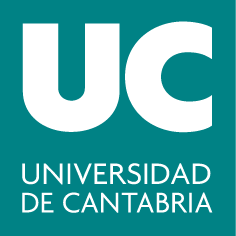

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 10: Aplicaciones lineales (I)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Obtención de la matriz de una aplicación lineal

- Cálculo del núcleo y la imagen de una aplicación lineal

**Matriz asociada a una aplicación **

Sea $f$ la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^2 \\
(x,y,z) \leadsto (x'=2x, y'=-3y+z) $$


Siempre podremos reescribirla en la forma $\vec{x'}=A\vec{x}$ del siguiente modo:


$$\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & -3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$


Siendo $A$ su matriz asociada en bases canónicas (o matriz estándar). Fíjate que al ser una aplicación que va de $\mathbb{R}^3$ en $\mathbb{R}^2$, $A$ es de tamaño $2 \times 3$. Una vez tenemos $A$, es muy fácil calcular el transformado (es decir, la imagen), de cualquier vector del espacio vectorial inicial, $\mathbb{R}^3$. Por ejemplo, la imagen del $(5,-7,-\pi)$ en $\mathbb{R}^2$ será:

A = [2 0 0; 0 -3 1]  % matriz estándar de f
A*[5 -7 -pi]'  % imagen por f del vector (5, -7, -pi)

Se puede comprobar fácilmente que las columnas de $A$ se corresponden con la imagen por $f$ de los vectores de la base canónica del espacio inicial:

A*[1 0 0]'  % primera columna de A (imagen del primer vector de la BC de R³
A*[0 1 0]'  % segunda columna de A (imagen del segundo vector de la BC de R³)
A*[0 0 1]'  % tercera columna de A (imagen del tercer vector de la BC de R³)

Imaginemos ahora que nos pidieran la matriz asociada a $f$ en otras bases que no fueran las canónicas, por ejemplo $B =\lbrace (1,0,1), (0,-1,-3), (-2,1,0)\rbrace$ en $\mathbb{R}^3$ y $B' = \lbrace (1,1), (2,-1) \rbrace$ en $\mathbb{R}^2$. Para hallar dicha matriz, $M$, necesitaremos la matriz de paso de $B$ a la base canónica de $\mathbb{R}^3$ (llamémosla $P$)  y la matriz de paso de $B'$ a la base canónica de $\mathbb{R}^2$ (llamémosla $Q$). Sabemos que $P=\left\lbrack \begin{array}{ccc}
1 & 0 & -2\\
0 & -1 & 1\\
1 & -3 & 0
\end{array}\right\rbrack$y $Q=\left\lbrack \begin{array}{cc}
1 & 2\\
1 & -1
\end{array}\right\rbrack$. A partir de aquí sería inmediato obtener $M$, pues sabemos que se cumple la relación $M=Q^{-1}AP$.  

P = [1 0 1; 0 -1 -3; -2 1 0]'  % matriz de paso de B a la BC de R³
Q = [1 1; 2 -1]'  %  matriz de paso de B' a la BC de R²
M = inv(Q)*A*P  % matriz de f en la bases B y B'

**Núcleo e imagen**

Una vez tenemos la matriz de la aplicación, es muy fácil hallar su núcleo (o *kernel*). Recuerda que el núcleo lo forman los vectores del espacio inicial cuya imagen por $f$ es el $\vec{0}$ del espacio final. Por tanto, partiendo de la matriz estándar $A$, nuestro problema se reducirá a resolver el sistema homogéneo cuya matriz de coeficientes es precisamente $A$, lo que nos devolverá directamente una base de $Ker(f)$:

baseKer = null(A, 'r')  % base de Ker(f) --> dim(Ker(f))=1

Para comprobar que la base que hemos obtenido es correcta, podríamos ver que la imagen del vector que la forma es el $\vec{0}$de $\mathbb{R}^2$:

A*baseKer  % al aplicarle A a la base de Ker(f), obtengo el vector 0 de R²

Por otro lado, sabemos que $Im(f)$ es el subespacio generado por las columnas de $A$, por lo cual, una base de $Im(f)$ será la formada por las columnas de $A$ que sean linealmente independientes:

null(A, 'r')  % sólo hay dos columnas L.I. en A, la primera y otra,
% a escoger entre la segunda y la tercera
base1Im = A(:, 1:2);  % esta sería una base de Im(f) --> dim(Im(f))=2 
base2Im = A(:, [1, 3]);  % esta sería otra base de Im(f) --> dim(Im(f))=2 

Date cuenta de que se cumple la relación de dimensiones $dim(Ker(f))+dim(Im(f))=n$, donde $n$ es la dimensión del espacio vectorial inicial. En nuestro caso particular tendríamos $1+2=3$. Además, por definición, $rg(f)=rg(A)=dim(Im(f))$.

#### Ejercicios propuestos

**Ejercicio 1:**

Dada la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^4 \longrightarrow  \mathbb{R}^3 \\
(x,y,z,t) \leadsto (x+2y+t , y+3z-t , 0) $$


- *a)* Obtén la forma implícita del núcleo y de la imagen de $f$

- *b)* Clasifica $f$

- *c)* Halla los vectores que tienen como imagen el vector $(2,2,0)$

- *d)* Halla los vectores que tienen como imagen el vector $(2,2,2)$

- *e)* Calcula una base de la imagen del subespacio $S$ de $\mathbb{R}^4$ engendrado por los vectores $\lbrace (0,0,3,2),(4,6,3,-1),(1,0,0,2) \rbrace$

**Ejercicio 2:**

Dada la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^2 \\
(x,y,z) \leadsto (3x-2y, x-z) $$


- *a)* ¿Cuál es el rango de $f$?

- *b)* Obtén una base del núcleo de $f$

- *c)* Obtén una base de la imagen de $f$

- *d)* Clasifica $f$

- *e)* Obtén una base de la imagen del subespacio $S \in \mathbb{R}^3$ cuya ecuación implícita es $x+y+z=0$

- *f)* Obtén la matriz de $f$ en las bases $B=\lbrace (1,0,-1), (0,2,3), (0,-1,0)\rbrace$ de $\mathbb{R}^3$ y $B' = \lbrace (1,0), (-1,2)\rbrace$ de $\mathbb{R}^2$

**Ejercicio 3:**

Sea $\mathit{f}: \mathbb{R}^4 \longrightarrow  \mathbb{R}^4$ una aplicación lineal que verifica las siguientes condiciones:

- Los vectores $(1,1,1,1)$ y $(1,1,1,0)$ se transforman por $f$ en $(1,1,0,0)$ y $(1,0,0,0)$, respectivamente

- $f^2$ es la aplicación nula

Halla su matriz estándar.

**Ejercicio 4:**

Dada una aplicación lineal $\mathit{f}: \mathbb{R}^4 \longrightarrow  \mathbb{R}^4$ tal que su núcleo es el subespacio de ecuaciones $\lbrace x + y + z = 0,  t = 0 \rbrace$ y los vectores $\lbrace (1,1,1,0), (0,0,0,1) \rbrace$ se transforman por $f$ en sí mismos. Obtén:

- *a)* Su matriz asociada en la base canónica de $\mathbb{R}^4$ (matriz estándar)

- *b)* La imagen del subespacio $S$ de $\mathbb{R}^4$ cuyas ecuaciones implícitas son $\lbrace x + y + z = 0, t = 0, x - y + 2 t = 0 \rbrace$. ¿Qué puedes decir sobre $S$?

- *c)* La matriz de $f$ en la base $B=\lbrace(-1,0,0,0),(1,0,-2,3),(1,-1,0,2),(-1,-1,-1,0)\rbrace$de $\mathbb{R}^4
$